# Trabalho de EE-254 (Controle Preditivo): Parte 1

Considere o seguinte sistema de dois carros acoplados por uma mola:

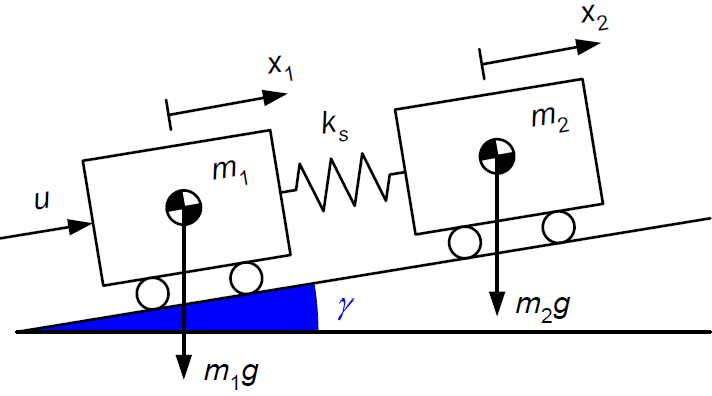

com deslocamentos $x_1$, $x_2$ definidos de modo que a mola esteja relaxada quando $x_1 = x_2$. O **ângulo de inclinação** $\gamma$ é constante, mas de **valor desconhecido**. 

A dinâmica deste sistema, a tempo contínuo, é descrita pelas seguintes equações:


$$m_1 \ddot{x}_1(t) = u(t) + k_s \big[\, x_2(t) - x_1(t) \,\big] - m_1 g \, \text{sen} \, \gamma$$



$$m_2 \ddot{x}_2(t) = - k_s \big[\, x_2(t) - x_1(t) \,\big] - m_2 g \, \text{sen} \, \gamma$$


que podem ser colocadas na forma 


$$\dot{x}(t) = A_c x(t) + B_c u(t) + E_c \bar{d}$$


com $x_3 = \dot{x}_1$, $x_4 = \dot{x}_2$, $\bar{d} = g \, \text{sen} \, \gamma$ e

$A_c =
\left[
  \begin{array}{cccc}
    0 & 0 & 1 & 0 \\[4pt]
    0 & 0 & 0 & 1 \\[4pt]
    -k_s/m_1 & k_s/m_1 & 0 & 0 \\[4pt]
    k_s/m_2 & -k_s/m_2 & 0 & 0 \\
  \end{array}
\right]$, $B_c =
\left[
  \begin{array}{c}
    0 \\[4pt]
    0 \\[4pt]
    1/m_1 \\[4pt]
    0 \\
  \end{array}
\right]$, $E_c =
\left[
  \begin{array}{c}
    0 \\[4pt]
    0 \\[4pt]
    -1 \\[4pt]
    -1 \\
  \end{array}
\right]$

Neste trabalho, serão adotados os seguintes valores para os parâmetros do modelo:

$m_1 = 5$ kg, $m_2 = 3$ kg, $k_s = 10$ N/m, $g = 9\text{,}8$ m/s${}^2$

que resultam nas matrizes $A_c$, $B_c$, $E_c$ definidas no código abaixo:

m1 = 5; m2 = 3; ks = 10; g = 9.8;
Ac = [0 0 1 0;
      0 0 0 1;
      -ks/m1 ks/m1 0 0;
      ks/m2 -ks/m2 0 0];
Bc = [0;0;1/m1;0];
Ec = [0;0;-1;-1];

A variável a ser controlada será o deslocamento do segundo carro, isto é, $y = x_2$. Essa é uma equação de saída da forma $y(t) = C x(t)$ com 

C = [0 1 0 0];


A tarefa de controle consiste em deslocar o segundo carro por uma distância de 1 m, com tempo de subida (10 % a 90 %) de até 6 s. Adicionalmente, deseja-se que a deformação da mola e o controle (ambos em módulo) não ultrapassem 0,05 m e 2 N, respectivamente, quando a inclinação for nula ($\gamma = 0$).

#### Item a (1,0 ponto)

Adotando um período de amostragem $T = 0\text{,}2$ s, discretize a equação de estado na forma


$$x(k+1) = A x(k) + B u(k) + E \bar{d}$$


considerando que o controle seja aplicado por meio de um segurador de ordem zero. 

T = 0.2; % sample

% E=Ec * dbar %%%%%%%%%%%%%%%%%%%%%%%%% verify
Sysc = ss(Ac, Bc, [], []);
Sys=c2d(Sysc, T, 'zoh');

A=Sys.A

A =     0.9607    0.0393    0.1974    0.0026
    0.0655    0.9345    0.0044    0.1956
   -0.3859    0.3859    0.9607    0.0393
    0.6432   -0.6432    0.0655    0.9345


B=Sys.B

B =     0.0040
    0.0000
    0.0395
    0.0009



[~, E] =c2dm(Ac, Ec, [], [], T, 'zoh')

E =    -0.0200
   -0.0200
   -0.2000
   -0.2000



% Aexp = expm(Ac*T)
% Bexp = inv(Ac)*(expm(Ac*T) - eye(4)) * Bc %% verify

poles = abs(eig(A)) % autovalores sao as raizes de um polinomio caracteristico

poles =     1.0000
    1.0000
    1.0000
    1.0000


**Resultado esperado:**

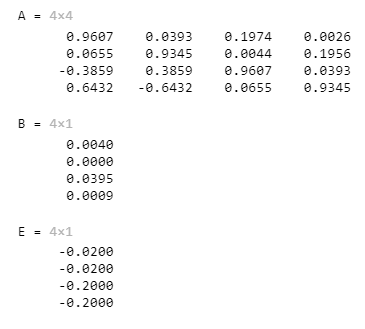

Desconsiderando inicialmente a presença da perturbação, vamos projetar uma lei de controle da forma


$$u(k) = -K (x(k) - \bar{x}) + \bar{u}$$


sendo $\bar{x}$, $\bar{u}$ os valores de equilíbrio desejados para o estado e o controle.

#### Item b (1,0 pontos) 

Determine $N_x$, $N_u$ de modo que $\bar{x} = N_x \bar{r}$ e $\bar{u} = N_u \bar{r}$, sendo $\bar{r}$ o valor de referência para a variável controlada $y$.

%aula 4
aux = inv([A - eye(4) B; C 0])*[0; 0; 0; 0; 1]

aux =     1.0000
    1.0000
    0.0000
    0.0000
    0.0000



Nx = aux(1:4,:)

Nx =     1.0000
    1.0000
    0.0000
    0.0000


Nu = aux(5)

Nu = 3.5567e-16


rbar=1;
ubar=Nu*rbar % + M*dbar ;

ubar = 3.5567e-16

xbar=Nx*rbar % + Mx*dbar ;

xbar =     1.0000
    1.0000
    0.0000
    0.0000


**Resultado esperado:**

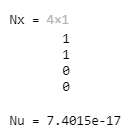

Constata-se, portanto, que $\bar{x}_1 = \bar{x}_2 = \bar{r}$, $\bar{x}_3 = \bar{x}_4 = 0$ e $\bar{u} = 0$ (a menos de imprecisão numérica), o que é consistente com a física do movimento do sistema.

Vamos projetar o ganho $K$ pelo método do regulador linear-quadrático, de modo a minimizar o custo


$$J = \sum_{k = 0}^{\infty} \Big[\, \mu_1(x_1(k) - \bar{x}_1)^2 + \mu_2(x_2(k) - \bar{x}_2)^2 + \mu_3x_3^2(k) + \mu_4x_4^2(k) + \mu_5(x_1(k) - x_2(k))^2 + \rho u^2(k) \, \Big]$$


sendo $\mu_1, \mu_2, \mu_3, \mu_4, \mu_5, \rho$ constantes positivas a serem ajustadas. Como $\bar{x}_3 = \bar{x}_4 = 0$ e $\bar{u} = 0$, o custo $J$ pode ser expresso, de forma equivalente, como


$$J = \sum_{k = 0}^{\infty} \Big[\, \|x(k) - \bar{x}\|^2_Q + \|u(k) - \bar{u}\|^2_R \, \Big]$$


com 

$Q =
\left[
  \begin{array}{cccc}
    \mu_1 + \mu_5 & - \mu_5 & 0 & 0 \\[4pt]
    -\mu_5 & \mu_2 + \mu_5 & 0 & 0 \\[4pt]
    0 & 0 & \mu_3 & 0 \\[4pt]
    0 & 0 & 0 & \mu_4 \\
  \end{array}
\right]$, $R = \rho$

#### Item c (1,0 pontos)

Considerando que a excursão das variáveis de estado e controle sejam tais que


$$|x_1 - \bar{x}_1|_{max} = |x_2 - \bar{x}_2|_{max} = 1 \text{ m}, |x_3|_{max} = |x_4|_{max} = (0,9 - 0,1) \text{m} / (6 \text{ s}), |x_1 - x_2|_{max} = 0,05 \text{ m}, |u|_{max} = {2} \text{ N}$$


utilize a regra de Bryson para escolher os pesos $Q$, $R$ e determine o ganho $K$do controlador.

% aula 5 - K cte (situação otima)
% erro -> 0

% proporcao distancia da mola

% regra bryson
% qii = 1/max mod(x_i)
% rjj=1/max mod(u_j)
q=1 % Q = Q_BAR and R = r * R_BAR

q = 1


x1 = 1

x1 = 1

x2 = 1

x2 = 1

x3_max = 0.8/6 % [m/s]

x3_max = 0.1333

x4_max = x3_max

x4_max = 0.1333

x1_x2_max = 0.05

x1_x2_max = 0.0500

u_max = 2 % rho

u_max = 2


mu1 = 1/x1^2

mu1 = 1

mu2 = mu1

mu2 = 1

mu3 = 1/(x3_max^2)

mu3 = 56.2500

mu4 = 1/(x4_max^2)

mu4 = 56.2500

mu5 = 1/(x1_x2_max^2) % spring noise affects u1 and u2

mu5 = 400.0000

rho = 1/(u_max^2)

rho = 0.2500


R = rho

R = 0.2500

Q = [mu1+mu5 -mu5 0 0; -mu5 mu2+mu5 0 0;0 0 mu3 0; 0 0 0 mu4]

Q =   401.0000 -400.0000         0         0
 -400.0000  401.0000         0         0
         0         0   56.2500         0
         0         0         0   56.2500



K = dlqr(A,B,Q,R)

K =    20.7514  -19.0366   18.1692   -3.5639


**Resultado esperado:**

#### Item d (2,0 pontos)

Simule o sistema em malha fechada, considerando inclinação nula ($\gamma = 0$) e empregando passo de simulação 10 vezes menor que o período de amostragem. Apresente gráficos da saída $y(t)$, da deformação da mola $x_1(t) - x_2(t)$e também do controle $u(t)$, do instante $t = 0$ ao instante $t = 20$ s. Determine o tempo de subida (10 % a 90 %) de forma computacional (isto é, por meio de código e não por inspeção visual dos gráficos).

% Parâmetros de simulação
dt = T/10;
% Defina o tempo total de simulação em segundos
tempo_total = 20;
t = 0:dt:tempo_total; % Vetor de tempo

%angulo inclinação
gamma=0;
dbar = g* sin(gamma) % perturbação cte

dbar = 0


Sys_sim=c2d(Sysc, dt, 'zoh');
Asim=Sys_sim.A

Asim =     0.9996    0.0004    0.0200    0.0000
    0.0007    0.9993    0.0000    0.0200
   -0.0400    0.0400    0.9996    0.0004
    0.0666   -0.0666    0.0007    0.9993


Bsim=Sys_sim.B

Bsim =     0.0000
    0.0000
    0.0040
    0.0000


[~, Esim] =c2dm(Ac, Ec, [], [], dt, 'zoh')

Esim =    -0.0002
   -0.0002
   -0.0200
   -0.0200


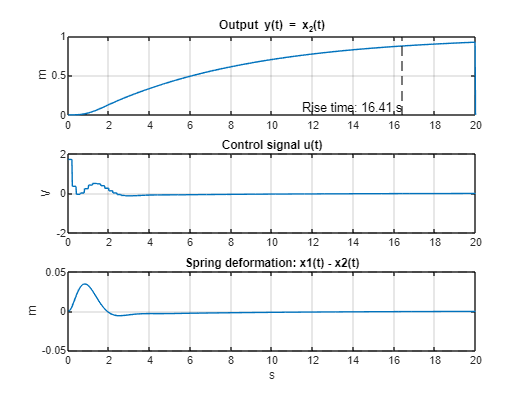


% Inicialização
nt = length(t);
x = zeros(4, nt); % 4 estados, cada coluna representa um tempo
u = zeros(1, nt); % 1 sinal de controle, cada coluna representa um tempo
y = zeros(1, nt); % 1 saída, cada coluna representa um tempo

% Loop for para simular a cada passo de simulação
for i = 1:nt-1
    % Control law
    if rem(i-1,10)==0
        uk = ubar - K * (x(:,i) - xbar);
    end
    u(i) = uk;
    if i < nt
        x(:, i+1) = Asim * x(:, i) + Bsim * u(i) + Esim * dbar;
    end
    y(i) = C * x(:, i);
end

S = stepinfo(y,t,1,0,'RiseTimeLimits',[0.1,0.9]);
RiseTime = S.RiseTime;

figure
subplot(3,1,1);
plot(t, y); hold on;
xline(RiseTime,'--black');
text(RiseTime,0,['Rise time: ',num2str(round(RiseTime,2)),' s'],'HorizontalAlignment','right','VerticalAlignment','bottom');
title('Output y(t) = x_2(t)');
ylabel('m');
grid on;

subplot(3,1,2);
plot(t, u); hold on;
yline(2,'--black');
yline(-2,'--black');
title('Control signal u(t)');
ylabel('V');
grid on;

subplot(3,1,3);
plot(t, x(1,:) - x(2,:)); hold on;
yline(0.05,'--black');
yline(-0.05,'--black');
title('Spring deformation: x1(t) - x2(t)');
ylabel('m');
xlabel('s');
grid on;

#### Item e (1,0 pontos)

Refaça o item (d), reajustando os pesos $Q, R$ de forma conveniente para atender as especificações de tempo de subida, deformação da mola e magnitude do controle.

% tentativa eerro - Insira seu código aqui
mu5 = 0; % para aproveitar melhor a restrição de oscilação
mu1 = mu1*5; % para fazer com que o sistema seja mais rápido
R = rho*20; % para ajustar a restrição de oscilação quando ela é violada.
Q = [mu1+mu5 -mu5 0 0; -mu5 mu2+mu5 0 0;0 0 mu3 0; 0 0 0 mu4]

Q =     5.0000         0         0         0
         0    1.0000         0         0
         0         0   56.2500         0
         0         0         0   56.2500



K = dlqr(A,B,Q,R)

K =     1.3304   -0.3639    5.7470    0.0221


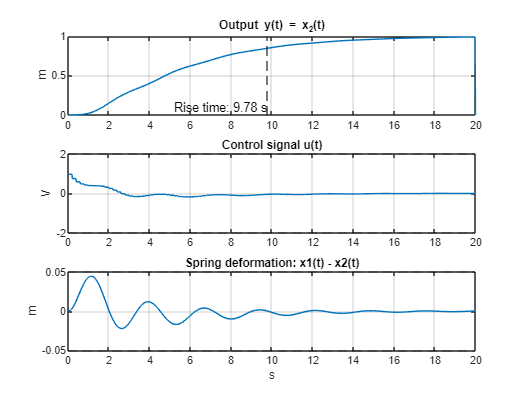


% Inicialização
nt = length(t);
x = zeros(4, nt); % 4 estados, cada coluna representa um tempo
u = zeros(1, nt); % 1 sinal de controle, cada coluna representa um tempo
y = zeros(1, nt); % 1 saída, cada coluna representa um tempo

% Loop for para simular a cada passo de simulação
for i = 1:nt-1
    % Control law
    if rem(i-1,10)==0
        uk = ubar - K * (x(:,i) - xbar);
    end
    u(i) = uk;
    
    
    if i < nt
        x(:, i+1) = Asim * x(:, i) + Bsim * u(i) + Esim * dbar;
    end
    y(i) = C * x(:, i);
end

S = stepinfo(y,t,1,0,'RiseTimeLimits',[0.1,0.9]);
RiseTime = S.RiseTime;

figure
subplot(3,1,1);
plot(t, y); hold on;
xline(RiseTime,'--black');
text(RiseTime,0,['Rise time: ',num2str(round(RiseTime,2)),' s'],'HorizontalAlignment','right','VerticalAlignment','bottom');
title('Output y(t) = x_2(t)');
ylabel('m');
grid on;

subplot(3,1,2);
plot(t, u); hold on;
yline(2,'--black');
yline(-2,'--black');
title('Control signal u(t)');
ylabel('V');
grid on;

subplot(3,1,3);
plot(t, x(1,:) - x(2,:)); hold on;
yline(0.05,'--black');
yline(-0.05,'--black');
title('Spring deformation: x1(t) - x2(t)');
ylabel('m');
xlabel('s');
grid on;

**Observação:** Caso não tenha sido possível completar o item (d), sugere-se usar o ganho abaixo, que atende as especificações para a tarefa de controle.

#### 

#### Item f (2,0 pontos)

Supondo que as variáveis de estado $x_1$, $x_2$, $x_3$, $x_4$ sejam todas medidas, projete um observador de estados *deadbeat* de modo a estimar o ângulo de inclinação $\gamma$.

Achi = [A E;zeros(1,4) 1];
Bchi = [B;0]; 
H = eye(4);
Hchi = [H zeros(4,1)];

eig_des = [0:4]*1e-6;  % 5 autovalores
L = place(Achi',Hchi',eig_des)'; % 4 sensores

L =     0.9604    0.0546    0.2361    0.0623
    0.0652    0.9498    0.0432    0.2553
   -0.3885    0.5387    1.3486    0.6364
    0.6407   -0.4905    0.4534    1.5316
    0.0127   -0.7637   -1.9394   -2.9855


M = inv(Achi)*L

M =     1.0000   -0.0000    0.0000    0.0000
   -0.0000    1.0000    0.0000    0.0000
   -0.0000    0.0000    1.0000    0.0000
    0.0000   -0.0000   -0.0000    1.0000
    0.0127   -0.7637   -1.9394   -2.9855



eig(Achi - M*Hchi*Achi)

ans = 	1.0e+-5 *

   -0.0000
    0.4000
    0.1000
    0.2000
    0.3000


# A matriz E não é igual à matriz B. Vide item (a).

**Observação: **O observador será implementado fazendo uso do seguinte estado aumentado: 


$$\chi(k) =
\left[
  \begin{array}{c}
    x(k) \\[4pt]
    d(k) \\
  \end{array}
\right]$$


e as seguintes equações:  


$$\chi(k|k) = \chi(k|k-1) + M\big[z(k) - z(k|k-1)\big]$$



$$z(k|k-1) = H_\chi \chi(k|k-1)$$



$$\chi(k+1|k) = A_\chi \chi(k|k) + B_\chi u(k)$$


com $z(k) = x(k)$e matrizes $A_\chi$, $B_\chi$, $H_\chi$ definidas de forma conveniente. A menos de imprecisão numérica, espera-se que seja obtida a seguinte matriz de ganho $M$:

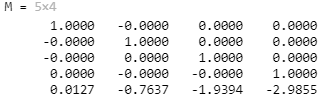

#### Item g (2,0 pontos) 

Utilizando o controlador sintonizado no item (e) e o observador projetado no item (f), refaça a simulação com inclinação $\gamma = 0,5^\circ$. Apresente gráficos da saída $y(t)$, da deformação da mola $x_1(t) - x_2(t)$, da estimativa da perturbação $\bar{d}(k|k)$ e também do controle $u(t)$, do instante $t = 0$ ao instante $t = 20$ s. Espera-se que a saída $y = x_2$ convirja assintoticamente para o valor de referência, sem erro de regime estacionário. Neste caso, a deformação da mola tende a ser maior em comparação com o item (e), devido à presença da perturbação.

% deformação fica maior - lsim
% sis se deslocando 0.5 graus
g = 9.8;
gamma = 0.5;
dbar = g*sind(gamma);
aux = inv([A - eye(4) B;C 0])*[-E;0];
Mx = aux(1:4);

Mx =     0.3000
         0
    0.0000
         0


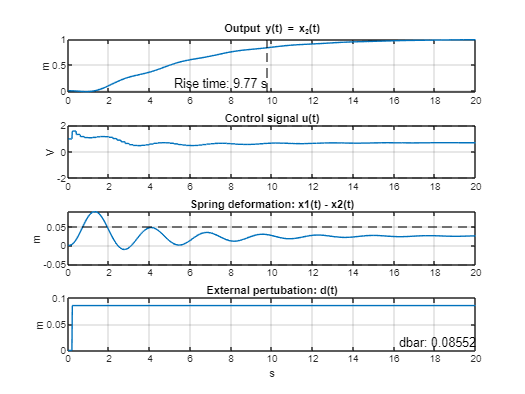

Mu = aux(5);

% Inicialização
nt = length(t);
x = zeros(4, nt); % 4 estados, cada coluna representa um tempo
u = zeros(1, nt); % 1 sinal de controle, cada coluna representa um tempo
y = zeros(1, nt); % 1 saída, cada coluna representa um tempo
d = zeros(1,nt);

chik = zeros(5,1);
% Loop for para simular a cada passo de simulação
for i = 1:nt 
    
    % o tempo da simulação é 0.2/10.
    % Mas, o controle só pode funcionar a cada 0.2 (s)
    % Ou seja, você deveria ter discretizado as matrizes A,B,C,D,E duas vezes:
    % 1. com T = 0.2 para projetar o controlador
    % 2. com dt = 0.02 para realizar a simulação
   
    % Control law
    if rem(i-1,10)==0
        chik = chik + M*(x(:,i)-Hchi*chik);
        dk = chik(5);
        ubar = Nu*rbar + Mu*dk;
        xbar = Nx*rbar + Mx*dk;
        uk = ubar - K * (x(:,i) - xbar);
        chik = Achi*chik + Bchi*uk;
    end
    d(i) = dk;
    u(i) = uk;
    if i < nt
        x(:, i+1) = Asim * x(:, i) + Bsim * u(i) + Esim * dbar;
    end
    y(i) = C * x(:, i);
end

S = stepinfo(y,t,1,0,'RiseTimeLimits',[0.1,0.9]);
RiseTime = S.RiseTime;

figure
subplot(4,1,1);
plot(t, y); hold on;
xline(RiseTime,'--black');
text(RiseTime,0,['Rise time: ',num2str(round(RiseTime,2)),' s'],'HorizontalAlignment','right','VerticalAlignment','bottom');
title('Output y(t) = x_2(t)');
ylabel('m');
grid on;


subplot(4,1,2);
plot(t, u); hold on;
yline(2,'--black');
yline(-2,'--black');
title('Control signal u(t)');
ylabel('V');
grid on;

subplot(4,1,3);
plot(t, x(1,:) - x(2,:)); hold on;
yline(0.05,'--black');
yline(-0.05,'--black');
title('Spring deformation: x1(t) - x2(t)');
ylabel('m');
grid on;

subplot(4,1,4);
plot(t,d);
text(20,0,['dbar = d(t=20s): ',num2str(d(end))],'HorizontalAlignment','right','VerticalAlignment','bottom');
title('External pertubation: d(t)');
ylabel('m');
xlabel('s');
grid on;